Problem 2-3

% We find the ellipsoid E of maximum volume that lies inside of
% a polyhedra C described by a set of linear inequalities.
%
% C = { x | a_i^T x <= b_i, i = 1,...,m } (polyhedra)
% E = { Bu + d | || u || <= 1 } (ellipsoid)
%
% This problem can be formulated as a log det maximization
% which can then be computed using the det_rootn function, ie,
%     maximize     log det B
%     subject to   || B a_i || + a_i^T d <= b,  for i = 1,...,m

n = 2;
px = [-0.5 4/7 1/3 -6/7];
py = [0.5 1/7 -1/3 1/7];
m = 4;
px = [px px(1)];
py = [py py(1)];
A = zeros(m,n); b = zeros(m,1);
A = [-1,1;2,-1;1,3;-2,-5];
b = [1;1;1;1;1];

% % generate A,b
% A = zeros(m,n); b = zeros(m,1);
% for i=1:m
%   A(i,:) = null([px(i+1)-px(i) py(i+1)-py(i)])';
%   b(i) = A(i,:)*.5*[px(i+1)+px(i); py(i+1)+py(i)];
%   if A(i,:)*[pxint; pyint]-b(i)>0
%     A(i,:) = -A(i,:);
%     b(i) = -b(i);
%   end
% end
% A
% b

% formulate and solve the problem
cvx_begin
    variable B(n,n) symmetric
    variable d(n)
    maximize( det_rootn( B ) )
    subject to
       for i = 1:m
           norm( B*A(i,:)', 2 ) + A(i,:)*d <= b(i);
       end
cvx_end

 
Calling SDPT3 4.0: 30 variables, 14 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 14
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of socp   var  = 12,   num. of socp blk  =  4
 dim. of linear var  =  5
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|1.2e+01|1.2e+03| 1.385641e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.741|7.8e-06|3.2e+00|3.3e+02| 3.397599e+01 -6.874381e+00| 0:0:00| chol  1  1 
 2|1.000|0.988|5.5e-06|4.9e-02|2.7e+01| 2.311574e+01 -9.692387e-02| 0:0:0

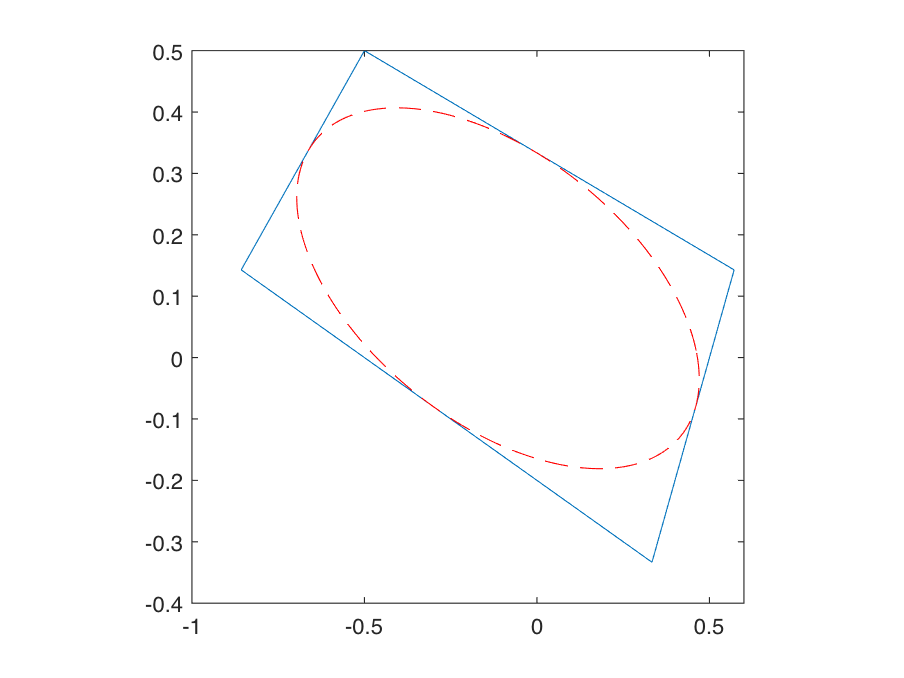


% make the plots
noangles = 400;
angles   = linspace( 0, 2 * pi, noangles );
ellipse_inner  = B * [ cos(angles) ; sin(angles) ] + d * ones( 1, noangles );
% ellipse_outer  = 2*B * [ cos(angles) ; sin(angles) ] + d * ones( 1, noangles );

clf
plot(px,py)
hold on
plot( ellipse_inner(1,:), ellipse_inner(2,:), 'r--' );
% plot( ellipse_outer(1,:), ellipse_outer(2,:), 'r--' );
axis square
% axis off
hold off

Problem 3-2

A= [0 1 0;0 0 1;-1 -3 -3];
b=[0;0;1];
c=[1;0;0];
n=3;
alpha = 0.7;
beta =0.1;
cvx_begin sdp
    variable P(3,3) symmetric;
    variable tau;
subject to
%     tau >= 0;
    P >= eye(3);
    [-(A'*P+P*A+beta*P+tau*alpha^2*c*c'),-P*b;-b'*P,-tau] >= eye(4);
cvx_end

 
Calling SDPT3 4.0: 16 variables, 7 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  7
 dim. of sdp    var  =  7,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.7e+01|3.6e+00|7.0e+02| 3.190000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.816|1.000|1.6e+01|3.6e-02|1.2e+02|-3.836751e+00  0.000000e+00| 0:0:00| chol  1  1 
 2|0.986|1.000|2.3e-01|3.6e-03|1.7e+00|-5.385362e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.6e-03|3.6e-04|1.9e-02|-6.032747e-04  0.000000e+

P

P =     7.1732    1.9919    0.9082
    1.9919   15.6596    2.7387
    0.9082    2.7387    3.1967


tau

tau = -16.8504

Problem 4-2

A1 = [-0.5,0.3,0.4;1,0,0;0,1,0];
A2 = [-0.7,0.1,-0.2;1,0,0;0,1,0];
A3 = [0.6,-0.7,0.2;1,0,0;0,1,0];
B = [1;0;0];
beta = 1;
n=3;
cvx_begin sdp
    variables X(n,n) Y(1,n) ;
subject to 
    X >= eye(n);

    (X*A1'+Y'*B'+A1*X+B*Y+beta.*X) == -semidefinite(n);
    (X*A2'+Y'*B'+A2*X+B*Y+beta.*X) == -semidefinite(n);
    (X*A3'+Y'*B'+A3*X+B*Y+beta.*X) == -semidefinite(n);
cvx_end

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  9
 dim. of sdp    var  = 12,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.3e+01|6.4e+00|1.2e+03|-7.800000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.726|0.699|2.3e+01|2.0e+00|3.8e+02|-4.958937e+01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.514|0.736|1.1e+01|5.2e-01|2.0e+02|-5.029730e+01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.746|1.000|2.8e+00|5.9e-04|7.0e+01|-1.877639e+01  0.000000e+


P=inv(X)

P =     0.0871    0.1323    0.0791
    0.1323    0.4019    0.2561
    0.0791    0.2561    0.2464


K=Y*inv(X)

K =    -4.1108   -7.3517   -4.4005
